# Train Yolo v2 object detector

## Initialize

clear; close all; clc; rng('default');

## Label the data with Video Labeler

% label the data from scratch
%videoLabeler('metmovie.mp4');
% use the session file
% videoLabeler('videoLabelingSession.mat');

Load the saved ground truth data

load('gTruth.mat');


## Convert the data to use for training

make a directory to save images

[~,~,~] = mkdir('trainingImages');

% Convert the labeled data from movie to images
trainingDataset = objectDetectorTrainingData(gTruth,'SamplingFactor',1,'WriteLocation','trainingImages');


学習用に抽出されたイメージをフォルダーに書き込みます: 
 trainingImages

metmovie.mp4 から抽出された 523 イメージを書き込んでいます...完了しました。


rng(0);

% setup the training data
shuffledIndices = randperm(height(trainingDataset));
idx = floor(0.9 * length(shuffledIndices) );
trainingData = trainingDataset(shuffledIndices(1:idx),:);
testData = trainingDataset(shuffledIndices(idx+1:end),:);

## Visualize the labeled data

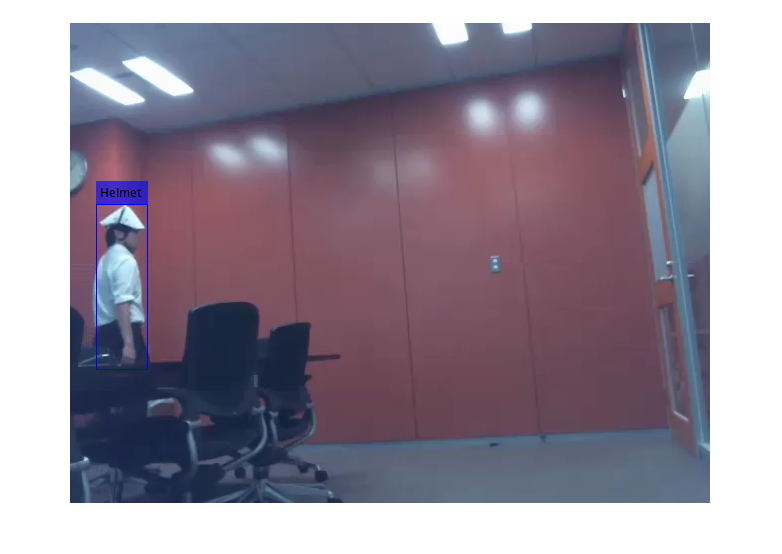

index = 1;
% define color map
cmaps = im2uint8(jet(width(trainingDataset)-1));
Iout = imread(trainingDataset.imageFilename{index});
for k = 1: width(trainingDataset)-1
    bboxes = table2array(trainingDataset(index,k+1));
    if ~isempty(bboxes{1})
        Iout = insertObjectAnnotation(Iout,'rectangle',bboxes{1},trainingDataset.Properties.VariableNames{k+1},'Color',cmaps(k,:));
    end
end
figure, imshow(Iout);

## Visualize bounding box distribution

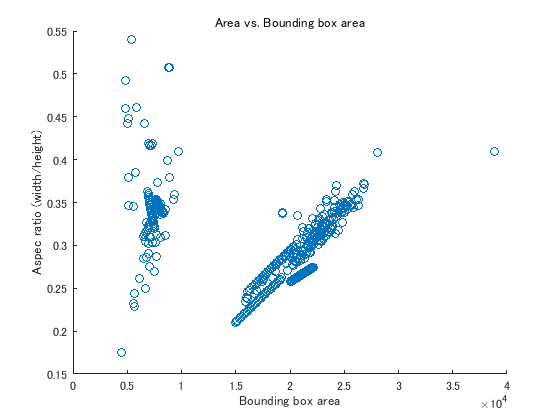

% Concatenate all bounding boxes
allBoxes = cell2mat(reshape(table2array(trainingDataset(:,2:end)),[],1));

% Plot bounding box area vs. aspect ratio
aspectRatio = allBoxes(:,3) ./ allBoxes(:,4);
area = prod(allBoxes(:,3:4),2);

figure
scatter(area,aspectRatio)
xlabel("Bounding box area")
ylabel("Aspec ratio (width/height)");
title("Area vs. Bounding box area")

## Cluster bounding boxes and determine anchor boxes

% Clustering into 4 groups
numAnchors = 4;

% Clustering data with K-Medoids
[clusterAssignments, anchorBoxes, sumd] = kmedoids(allBoxes(:,3:4),numAnchors,'Distance',@iouDistanceMetric);

% show the size of anchor boxes
disp(anchorBoxes);

   86.0625  268.4688
   55.0000  132.0000
   73.1250  270.3438
   51.7368  150.8947



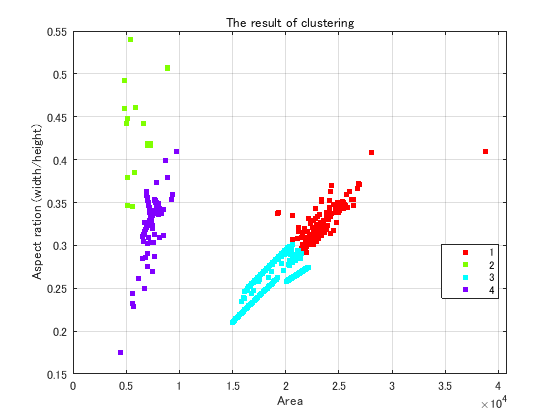


% plot the result of clustering
figure
gscatter(area,aspectRatio,clusterAssignments);
title("The result of clustering")
xlabel("Area")
ylabel("Aspect ration (width/height)");
grid


% Cumulative addition
counts = accumarray(clusterAssignments, ones(length(clusterAssignments),1),[],@(x)sum(x)-1);

%Calculate mean IoU
meanIoU = mean(1 - sumd./(counts));
disp("mean IoU : " + meanIoU);

mean IoU : 0.91616


## Confirm the relationship between the number of anchor boxes and the average IoU

Increasing the anchor box improves the average IoU but increases the computational complexity.

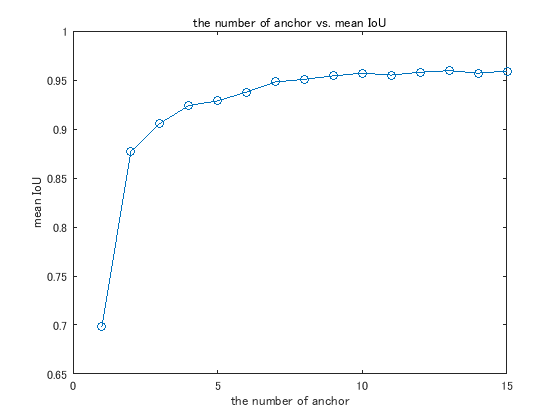


maxNumAnchors = 15;
for k = 1:maxNumAnchors
    
    % Clustering data with K-Medoids
    [clusterAssignments, ~, sumd] = kmedoids(allBoxes(:,3:4),k,'Distance',@iouDistanceMetric);
    
    % Calculate mean IoU
    counts = accumarray(clusterAssignments, ones(length(clusterAssignments),1),[],@(x)sum(x)-1);
    meanIoU(k) = mean(1 - sumd./(counts));
end

figure
plot(1:maxNumAnchors, meanIoU,'-o')
ylabel("mean IoU")
xlabel("the number of anchor")
title("the number of anchor vs. mean IoU")

## Prepare the model to train YOLO v2 object detector

% load pretrained model
network = resnet50();
% Specify the layer to be used for feature extraction
featureLayer = 'activation_40_relu';
% input image size
imageSize =[224 224 3];
% the number of classes
numClasses = width(trainingDataset)-1;
anchorBoxes(:,1) =anchorBoxes(:,1)*224/480;
anchorBoxes(:,2) =anchorBoxes(:,2)*224/680;
% define yolo v2 detector
lgraph = yolov2Layers(imageSize, numClasses, round(anchorBoxes), ...
    network, featureLayer);
% visualize network
%analyzeNetwork(lgraph)
options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.0001, ...
    'Verbose', true, 'MiniBatchSize', 16, 'MaxEpochs', 50,...
    'Shuffle', 'every-epoch', 'VerboseFrequency', 1);

## Train Yolo v2 network

doTraining = false;
if doTraining
    rng('default');
    tic;
    [detector,info] = trainYOLOv2ObjectDetector(trainingData,lgraph,options);
    toc
    save('trainedYOLOv2Detector','detector','info');
else
    load('trainedYOLOv2Detector');
end

## Object detection with trained YOLO v2

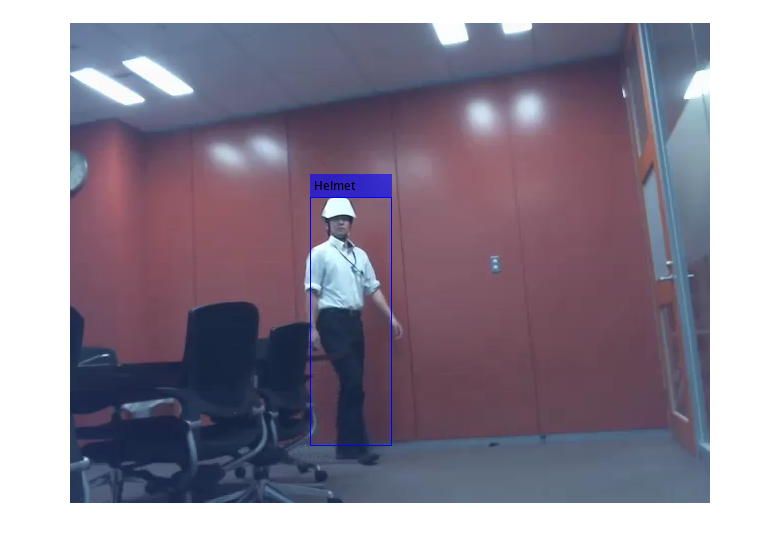

% read the test image
I = imread(trainingDataset.imageFilename{60});
% detect using trained model
[bboxes, scores, labels] = detect(detector, I);
% Colormap index generation for labels
[~,ind] = ismember(labels,gTruth.LabelDefinitions.Name);
% show the result
detectedImg = insertObjectAnnotation(I, 'Rectangle', bboxes, cellstr(labels),...
    'Color',cmaps(ind,:));
figure
imshow(detectedImg)

## Support functions

function dist = iouDistanceMetric(boxWidthHeight,allBoxWidthHeight)
% Calculate metric as distance based on IoU

% add x, y to caluculate IoU as bounding box
boxWidthHeight = prefixXYCoordinates(boxWidthHeight);
allBoxWidthHeight = prefixXYCoordinates(allBoxWidthHeight);

% Convert IoU to distance
dist = 1 - bboxOverlapRatio(allBoxWidthHeight, boxWidthHeight);
end

function boxWidthHeight = prefixXYCoordinates(boxWidthHeight)
% add x, y to caluculate IoU as bounding box
n = size(boxWidthHeight,1);
boxWidthHeight = [ones(n,2) boxWidthHeight];
end

*Copyright 2019 The MathWorks, Inc.*